format long

非法使用保留关键字 "for"。

ans =      2     4     8


E_dst = zeros(1,6)

E_dst =      0     0     0     0     0     0


EM_dst = zeros(1,6)

EM_dst =      0     0     0     0     0     0


N=[10,20,50,100,500,1000]

N =           10          20          50         100         500        1000


for i = 1:6
tic
U_dst=DSTPS(N(i));
toc
h=1/N(i);x=h:h:1-h;
[X,Y]=meshgrid(x,x);
Uexact=(1-X).*(1-Y).*sin(2*pi*X.*Y);
E_dst(i)=norm(U_dst-Uexact,'fro')/norm(Uexact,'fro')
EM_dst(i) =max(max(abs(U_dst -Uexact)))
end

历时 0.000262 秒。


E_dst =    0.009486444751920                   0                   0                   0                   0                   0


EM_dst =    0.002507993452062                   0                   0                   0                   0                   0


历时 0.000217 秒。


E_dst =    0.009486444751920   0.002357286945076                   0                   0                   0                   0


EM_dst =    0.002507993452062   0.000653268781902                   0                   0                   0                   0


历时 0.000413 秒。


E_dst =    0.009486444751920   0.002357286945076   0.000376513542707                   0                   0                   0


EM_dst =    0.002507993452062   0.000653268781902   0.000104805252438                   0                   0                   0


历时 0.000635 秒。


E_dst =    0.009486444751920   0.002357286945076   0.000376513542707   0.000094104996889                   0                   0


EM_dst =    0.002507993452062   0.000653268781902   0.000104805252438   0.000026184778598                   0                   0


历时 0.024082 秒。


E_dst =    0.009486444751920   0.002357286945076   0.000376513542707   0.000094104996889   0.000003763900312                   0


EM_dst =    0.002507993452062   0.000653268781902   0.000104805252438   0.000026184778598   0.000001047497115                   0


历时 0.153871 秒。


E_dst =    0.009486444751920   0.002357286945076   0.000376513542707   0.000094104996889   0.000003763900312   0.000000940972737


EM_dst =    0.002507993452062   0.000653268781902   0.000104805252438   0.000026184778598   0.000001047497115   0.000000261875460


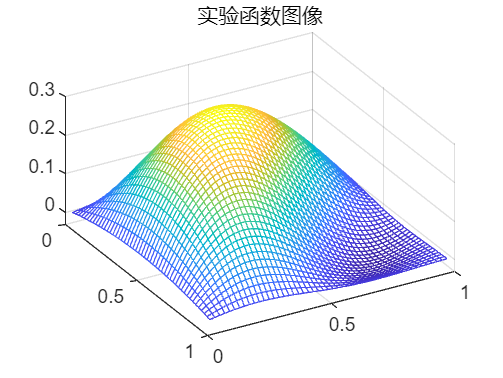

h=1/50;x=h:h:1-h;
[X,Y]=meshgrid(x,x);
Uexact=(1-X).*(1-Y).*sin(2*pi*X.*Y);
mesh(X,Y,Uexact)
view(60,45)
title('实验函数图像')

h=1/50;x=h:h:1-h;
[X,Y]=meshgrid(x,x);
U_dst=DSTPS(50);
mesh(X,Y,U_dst)
view(60,45)
title('计算结果图像')

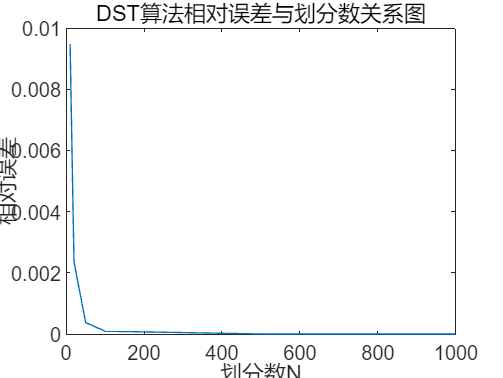

plot(N,EM_dst)
title('DST算法最大误差与划分数关系图')
xlabel('划分数N')
ylabel('最大误差')

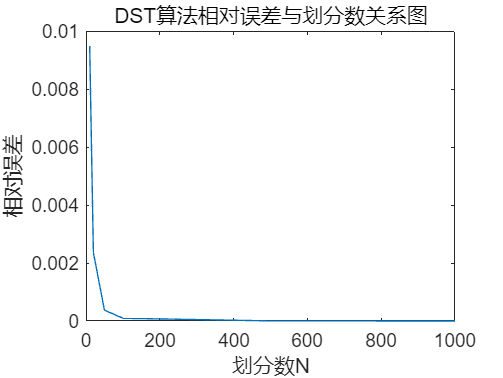


plot(N,E_dst)
title('DST算法相对误差与划分数关系图')
xlabel('划分数N')
ylabel('相对误差')

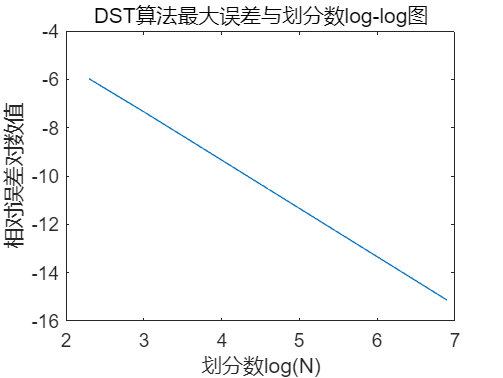

plot(log(N),log(EM_dst))
title('DST算法最大误差与划分数log-log图')
xlabel('划分数log(N)')
ylabel('相对误差对数值')

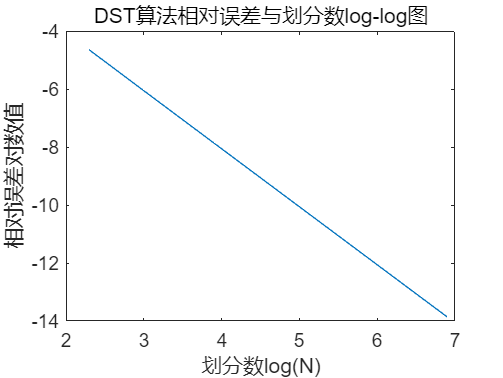

plot(log(N),log(E_dst))
title('DST算法相对误差与划分数log-log图')
xlabel('划分数log(N)')
ylabel('相对误差对数值')

p = polyfit(log(N),log(E_dst),1)

p =   -2.001298506975118  -0.053245140611604


pM = polyfit(log(N),log(EM_dst),1)

pM =   -1.993979792790152  -1.374410094256117
